# Robustness of CLF-Based Control

In this section we will examine how robust CLF-base control is in its nominal form, i.e. without additional robustifying terms such as Input to State Stable (ISS) CLFs, or Adaptive (a)CLFs. We will consider both the fully actuated pendulum dynamics and underactuated cartpole dynamics, and contexts of both desired state stabilization and trajectory tracking. 

We will consider robustness to several sources of uncertainty: 

- Sample and Hold: Digital control implementations will hold control actions constant over some sampling time. Continuous time controllers must still be effect when implemented with Sample and Hold strategies.

- Model Uncertainty: Here we will consider variations on the systems parameters as well as slight perturbations to the system dynamics. Ideally, a controller's performance is not completely degrade in the face of modeling uncertainty.

- Sensor Noise: Physical implementations rely on sensors to measure system states (and potentially observers to estimate complete system states from incomplete measurements). Sensor noise and delay induced by observers have the capability to impact system performance.

- Input Delays: In some systems, inputs do not impact the system immediately and are instead delayed by some amount of time. While long time delays are in general difficult to be robust to, a controller should be able to handle small delays which may included communication and computation times, as well as actuation dynamics.

- Combinations of the above: any physical system will always experience all of the above uncertainties to some extend. Good controllers must be able to tolerate some simultaneous deviations in all of the uncertainty categories above. 

The controllers we will be comparing: 

- PD control: synthesis of PD gains from linearization about an equilibrium position.

- Feedback linearization

- Minimum norm CLF-QP

- u-CLF-QP (or t-CLF-QP for time-based trajectories)

- Model Predictive Control

Note that the explicit and optimization-solver based QPs were all shown to give identical outputs in the CLF script. We will use explicit implementations here.

clear; clc; close all;
addpath("../Models")
addpath("../Simulators/")
addpath("../QPs")

## Sample and Hold Robustness

First, we examine robustness to sample-and-hold implementations of continuous controllers. This does not impact model-predictive controllers, which are natively designed to run in this fashion, and do not compute continuous inputs; however, all other controllers will be effected. 

First, lets instantiate the pendulum dynamics, and synthesize a CLF from feedback linearization. The goal will be to stabilize the pendulum to a desired angle $\theta_D$. 

thetaD =1.1;

xD = [thetaD; 0];
F = [0 1; 0 0];
G = [0; 1];
Q = eye(2);
R = 1;
K = lqr(F, G, Q, R);

m = 1; g = 9.81; L = 0.5;
params.m = m; params.g = g; params.L = L;

A_cl = [0 1; -K];
P = lyap(A_cl', eye(2));
lambda = 1 / max(eig(P));

eta = @(x) [x(1, :) - thetaD; x(2, :)];
V = @(x) eta(x)' * P * eta(x);
LfV = @(x) 2 * eta(x)' * P * pendulum_f(x, params);
LgV = @(x) 2 * eta(x)' * P * pendulum_g(x, params);
LFV = @(x) eta(x)' * (F' * P + P * F) * eta(x);
LGV = @(x) 2*eta(x)' * P * G;
DLfy = [0 1];
calF = @(x) DLfy * pendulum_f(x, params);
calG = @(x) DLfy * pendulum_g(x, params);

And now we instantiate the various controllers. 

fbl_ctrl = @(x) m*L^2 *(-g/L*sin(x(1, :)) -K*(x - xD));
mn_ctrl = @(x) kQP_explicit(lambda, V(x), LfV(x), LgV(x));
uCLFQP = @(x) kuQP_explicit(lambda, calG(x), calF(x), LFV(x), LGV(x), V(x));

Apend = [0 1; g/L*cos(thetaD) 0];
Bpend = [0; 1 / (m * L^2)];
u_eq = m*L^2 * -g/L*sin(thetaD);
Qp = eye(2); 
Rp = 1;
Kpd = lqr(Apend, Bpend, Qp, Rp);
pd_ctrl = @(x) u_eq -Kpd*(x - xD);

And finally, we analyze the performance of the controllers with a sample and hold implementation

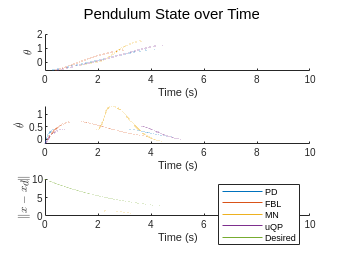

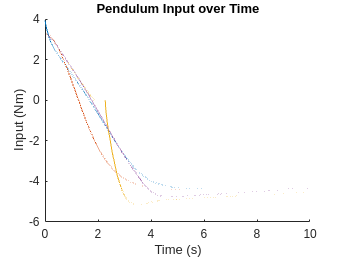

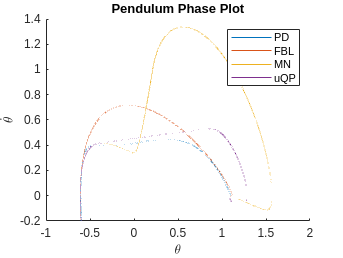

dt =0.01;
theta0 =-0.6;
thetadot0 = -0.2;
t0 = 0; tf = 10;
x0 = [theta0; thetadot0];

[t_pd, x_pd, u_pd] = sampleHoldSim(@pendulum, pd_ctrl, [t0, tf], x0, dt, params);
[t_fbl, x_fbl, u_fbl] = sampleHoldSim(@pendulum, fbl_ctrl, [t0, tf], x0, dt, params);
[t_mn, x_mn, u_mn] = sampleHoldSim(@pendulum, mn_ctrl, [t0, tf], x0, dt, params);
[t_u, x_u, u_u] = sampleHoldSim(@pendulum, uCLFQP, [t0, tf], x0, dt, params);

pendulum_plot( ...
    {t_pd, t_fbl, t_mn, t_u, t_pd}, ...
    {x_pd, x_fbl, x_mn, x_u, xD * ones(size(t_pd))}, ...
    {u_pd, u_fbl, u_mn, u_u}, ...
    sqrt(max(eig(P)) / min(eig(P)))*exp(-1/(2*max(eig(P))) * t_pd) * V(x0),...
    {'PD', 'FBL', 'MN', 'uQP', 'Desired'} ...
)